% y=1-\sigma(A_i * x^i)

A= [1.0000,...
    -4.8443 * 10^(-4),...
    -1.7111 * 10^(-6),...
    -1.3122 * 10^(-8),...
    3.0069 * 10^(-11),...
    -9.6714 * 10^(-15),...
    -8.0075 * 10^(-18)];
x=[0:650];
y=ones(1,651);
s=zeros(1,651);
for i = 1:7
    % for j = 1:651
    %     xi(j) = x(j)^(i-1);
    % end
    sigma = x.^(i-1) .* A(i);
    s=s+sigma;
end
y=1-s;

CR = [2.10, 0.70, 2.08, 2.13, 0.68, 2.01];
for i = 1 : 6
    CRW{i} = y .* CR(i);
end

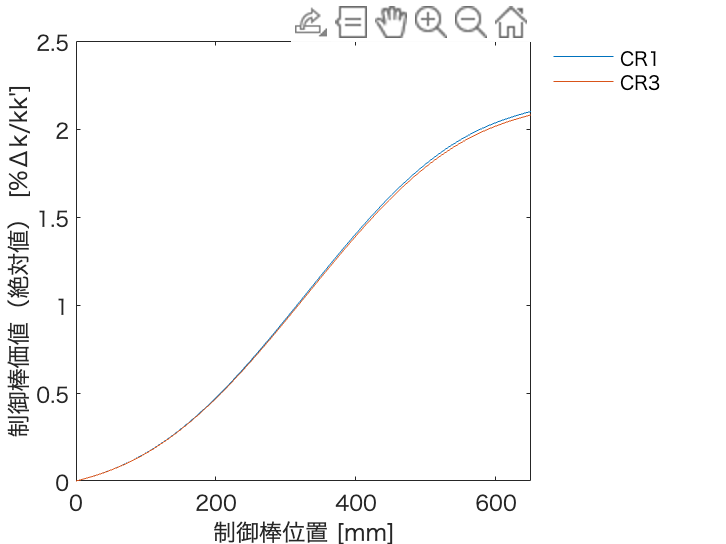

plot(x,CRW{1})
legend('CR1')
legend('boxoff')
legend('Location','northeastoutside')
xlabel('制御棒位置 [mm]')
ylabel('制御棒価値（絶対値） [%Δk/kk'']')
xlim([0 650])
hold on
% plot(x,CRW{2},DisplayName='CR2')
plot(x,CRW{3},DisplayName='CR3')
% plot(x,CRW{4},DisplayName='CR4') 
% plot(x,CRW{5},DisplayName='CR5')
% plot(x,CRW{6},DisplayName='CR6')
hold off

ControlRodNo = ['CR1';'CR2';'CR3';'CR4';'CR5';'CR6'];
reactivity = [CR(1)-CRW{1}(301);CR(2)-CRW{2}(301);CR(3)-CRW{3}(301);...
                CR(4)-CRW{4}(301);CR(5)-CRW{5}(301);CR(6)-CRW{6}(301)];
ans=table(ControlRodNo,reactivity);
ans.Properties.VariableNames("ControlRodNo") = "Control Rod No.";
ans.Properties.VariableNames("reactivity") = "Reactivity [Δk/kk'']";
ans.Properties.VariableUnits = ["","Δk/kk "];
ans

ans = 6×2 table
    Control Rod No.    Reactivity [Δk/kk'']
    _______________    ____________________

          CR1                 1.1773       
          CR2                0.39242       
          CR3                  1.166       
          CR4                 1.1941       
          CR5                0.38121       
          CR6                 1.1268       


CRW{1}(651)-CRW{1}(301)

ans = 1.1773

CRW{2}(651)-CRW{2}(301)

ans = 0.3924

a=0;
for i = 1:6
    a=a+CRW{i}(651);
end
a

a = 9.7002

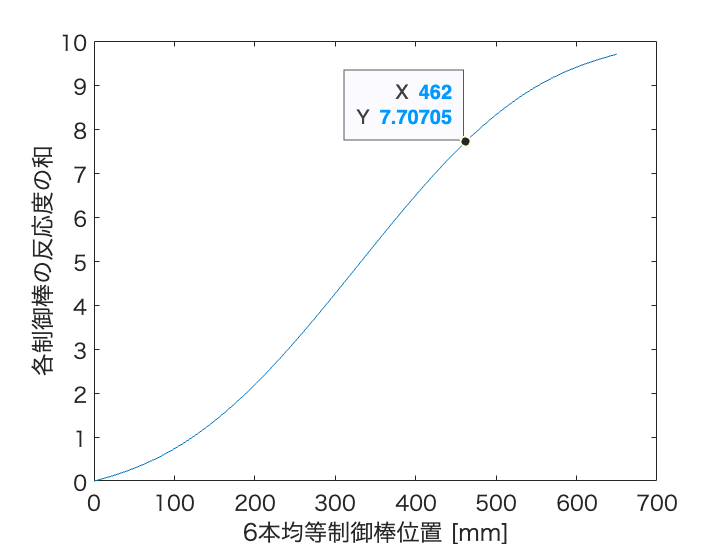

CRW_sum = CRW{1}+CRW{2}+CRW{3}+CRW{4}+CRW{5}+CRW{6};
plot(x,CRW_sum)
xlabel('6本均等制御棒位置 [mm]')
ylabel('各制御棒の反応度の和')
ax = gca;
chart = ax.Children(1);
datatip(chart,462,7.707,Location="northwest");

CRW_sum(1,462)

ans = 7.6893

CRW_sum(1,463)

ans = 7.7071

beta_eff = 4.38 * 10^(-3)

beta_eff = 0.0044

re_1 = CRW{1} *0.01 / beta_eff

re_1 =          0    0.0023    0.0047    0.0070    0.0094    0.0118    0.0142    0.0167    0.0191    0.0216    0.0241    0.0266    0.0292    0.0317    0.0343    0.0369    0.0395    0.0422    0.0448    0.0475    0.0502    0.0529    0.0557    0.0585    0.0613    0.0641    0.0670    0.0699    0.0728    0.0757    0.0786    0.0816    0.0846    0.0877    0.0907    0.0938    0.0969    0.1001    0.1033    0.1065    0.1097    0.1130    0.1162    0.1196    0.1229    0.1263    0.1297    0.1331    0.1366    0.1401


index = [0:650];
re = [index;re_1]'

re =          0         0
    1.0000    0.0023
    2.0000    0.0047
    3.0000    0.0070
    4.0000    0.0094
    5.0000    0.0118
    6.0000    0.0142
    7.0000    0.0167
    8.0000    0.0191
    9.0000    0.0216


T=100/log(2);

beta_i= [1.330 * 10^(-4),...
    9.355 * 10^(-4),...
    8.222 * 10^(-4),...
    1.670 * 10^(-3),...
    6.470 * 10^(-4),...
    1.717 * 10^(-4)];
lambda_i= [1.282 * 10^(-2),...
    3.146 * 10^(-2),...
    1.261 * 10^(-1),...
    3.291 * 10^(-1),...
    1.393,...
    3.796];
l_p=3.407 * 10^(-7);



rh = 0;
for i = 1:6
    si=beta_i(i)/(1+lambda_i(i)*T);
    rh=rh+si;
end
rh

rh = 2.9638e-04

rho=l_p/(T+l_p)+T*rh/(T+l_p)

rho = 2.9638e-04